# Plotting V-n Diagram

## Assumptions

- The pitching acceleration is assumed zero or negligible,

-  the airspeed is constant during the maneuver,

- there is no rolling or yawing of the aircraft,

- the gust affects the entire aircraft

## Required Infomation

- maximum positive load factor: $n_1 >1$

- maximum negative load factor: $n_3 <0$

- maximum level flight cruise speed: $V_C$

- maximum dive speed: $V_D$; $1\ldotp 2V_C \le V_D \le 1\ldotp 5V_C$; in this example: $V_D =1\ldotp 25\;V_C$

- weight of the aircraft :$W$

- desnity of the air at a specific altitude: $\rho_a$

- density of the air at sea level: $\rho_{\textrm{SL}}$

- acceleration due to gravity: $g$

- reference wing surface area: $S$

- mean aerodynamic chord: $\bar{c}$

- slope of the $C_L -\alpha$ curve for the combined wing and body: $a_{\textrm{BW}}$

- Rough air gust: $U_B =20\;\frac{m}{s}\;\left(66\;\frac{\textrm{ft}}{s}\right)$ at $V=V_B$ a speed related to the stall speed

- High speed gust: $U_C =15\ldotp 2\;\frac{m}{s}\;\left(50\;\frac{\textrm{ft}}{s}\right)$ at cruise speed $V_C$

- Dive speed gust: $U_D =7\ldotp 6\;\frac{m}{s}\;\left(25\;\frac{\textrm{ft}}{s}\right)$ at dive speed $V_D$

- mass parameter: $\mu_G =\frac{2W}{\rho_a \;g\;S\;\bar{\;c} \;a_{\textrm{BW}} }$

- The gust alleviation factor: $K_g =\frac{{0\ldotp 88\mu }_G }{5\ldotp 3+\mu_G }$

- Maximum negative load factor: $n_3 =-1$

- 
$$C_{Z_{\max } } =6$$


- 
$$C_{Z_{\min } } =-4$$


W=185000; S=50; c_bar=50/19; %M=7259;
a_BW=4.6; rho_SL=1.225; rho_a=0.2625; g=9.81; 
U_B=20; U_C=15.2; U_D=7.6; V_stall=220*0.2777777777778;
C_z_max=(2*W)/(rho_SL*S*V_stall^2) 

C_z_max = 1.6175

C_z_min=-0.6*C_z_max

C_z_min = -0.9705

mu_g=2*W/(rho_SL*g*S*c_bar*a_BW)

mu_g = 50.8689

K_g=0.88*mu_g/(5.3+mu_g)

K_g = 0.7970

## Formulas

### Incremental gust load factor


$$\Delta \;n=\pm K_g \;\;\frac{\rho_{\textrm{SL}} \;S\;v_{\textrm{dg}} \;V_E \;a_{\textrm{BW}} }{2W}\;$$


where $v_{\textrm{dg}}$ can be $U_B$, $U_C$, or $U_D$ depending on the aricraft maneuver, and $V_E$ is equivalent airspeed at the sea level which can is calculated as follow.


$$V_E =\sqrt{\frac{\rho_a \;}{\rho_{\textrm{SL}} }\;}V$$


where $V$ and $\rho_a \;$are the speed of the aircraft and the air density at a particular altitude. 

### Gust load factor

For steady level flight: $n=1\pm \Delta \;n=1\pm K_g \;\;\frac{\rho_{\textrm{SL}} \;S\;v_{\textrm{dg}} \;V_E \;a_{\textrm{BW}} }{2W}\;$

### Maximum positive load factor

$n_1 =2\ldotp 1+\frac{24,000}{W+10,000}$, W should be in lbf. 

From aircraft structures for engineering students, 5th edition, page 420.

n1=2.5

n1 = 2.5000

### Maximum negative load factor

From aircraft structures for engineering students, 5th edition, page 420.

n3=-1.25

n3 = -1.2500

## Calculating speeds and increment gust load factors 

syms U V

### Calculating $V_A$

Finding the intersection of the positive stall curve and the maximum positive load factor line:

eq=C_z_max*(rho_SL*S*V^2/(2*W))-n1==0;
V_A=double(max(solve(eq)))

V_A = 96.6252

### Calculating $V_F$

Finding the intersection of the negative stall curve and the maximum negative load factor line:

eq=C_z_min*(rho_SL*S*V^2/(2*W))-n3;
V_F=double(max(solve(eq)))

V_F = 88.2063

### Defning increment gust load factor

Delta_n=K_g*U*V*(rho_SL*a_BW*S/(2*W));

### Calculating $V_B$

Finding the intersection of the rough area load factor line and the maximum positive load factor line:

The rough area load factor line is the green dashed line whose corrosponding command line is commented.

eq=1+subs(Delta_n,U,U_B)-n1;
V_B=double(solve(eq))

V_B = 123.5833

### Calculating $V_{\textrm{B1}}$

Finding the intersection of the rough area load factor line and the  positive stall line:

eq=C_z_max*(rho_SL*S*V^2/(2*W))-1-subs(Delta_n,U,U_B);
V_B1=double(max(solve(eq)))

V_B1 = 87.8428

### Calculating $V_{\textrm{S1}}$

Finding the intersection of the imaginary line representing the steady level flight without gust (n=1) and the positive stall line:

eq=C_z_max*(rho_SL*S*V^2/(2*W))-1;
V_S1=double(max(solve(eq)))

V_S1 = 61.1111

### Calculating $V_C$ and $V_D$

The values or expressions for calculating these values are given.

V_C=V_B+20

V_C = 143.5833

V_D=1.25*V_C

V_D = 179.4792

### Calculating incremental gust load factors

Delta_n_rough=double(subs(Delta_n,[U V],[U_B V_B1]))

Delta_n_rough = 1.0662

Delta_n_cruise=double(subs(Delta_n,[U V],[U_C V_C]))

Delta_n_cruise = 1.3245

Delta_n_dive=double(subs(Delta_n,[U V],[U_D V_D]))

Delta_n_dive = 0.8278

### Specifying the points on the gust V-n diagram

gust_velocity=[V_B1,V_C,V_D,V_D,V_C,V_B1];
gust_load_factor=[1+Delta_n_rough,1+Delta_n_cruise,1+Delta_n_dive,...
    1-Delta_n_dive,1-Delta_n_cruise,1-Delta_n_rough];

## Plotting V-n diagram

### Plotting maneuver V-n diagram

syms v
upper_curve=C_z_max*rho_SL*S*v^2/(2*W);
lower_curve=C_z_min*rho_SL*S*v^2/(2*W);
branch1=fplot(upper_curve,[0 V_A],'k','LineWidth',1.5);
hold on
branch2=fplot(n1,[V_A V_D],'k','LineWidth',1.5);
branch3=plot([V_D,V_D],[n3,n1],'k','LineWidth',1.5);
branch4=fplot(n3,[V_F V_D],'k','LineWidth',1.5);
branch5=fplot(lower_curve,[0 V_F],'k','LineWidth',1.5);

### Plotting gust V-n diagram

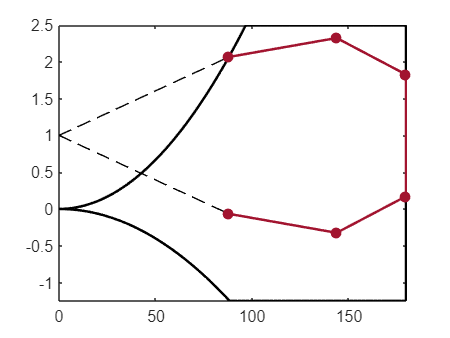

plot([0,V_B1],[1,1+Delta_n_rough],'--k')
% plot([0,V_B],[1,1+subs(Delta_n,[U,V],[U_B,V_B])],'--g')
plot([0,V_B1],[1,1-Delta_n_rough],'--k')
branch6=plot(gust_velocity,gust_load_factor,'color','#A2142F','LineWidth',1.5,'Marker','o','MarkerSize',5,...
    'MarkerEdgeColor','#A2142F','MarkerFaceColor','#A2142F');

### Formatting and printing the diagram

plot_style1('Load Factor','Equivalent Airspeed')

Unrecognized function or variable 'plot_style'.

text_pos_x=[1.01,1.01,1.01,1.01,1.01,1.01,1.01,1.01];
text_pos_y=[0.8,0.7,0.6,0.5,0.4,0.3,0.2,0.1];
strings={'$V(m/s)$',['$V_{S1}=$' num2str(V_S1,4)],['$V_{B1}=$' num2str(V_B1,4)], ['$V_F=$' num2str(V_F,4)], ['$V_A=$' num2str(V_A,4)], ['$V_{C}=$' num2str(V_C,4)],['$V_B=$' num2str(V_B,4)], ['$V_D=$' num2str(V_D,4)]};
text(text_pos_x,text_pos_y,strings,'FontUnits','points','FontWeight','normal','interpreter','latex','FontSize',12,'Units','normalized','FontName','Times New Roman')
figs=[branch1,branch6];
legend(figs,'Maneuver V-n Diagram','Gust V-n Diagram','Location','northeast')
xticks([V_S1 V_F V_A V_C V_D])
xticklabels({'$V_{S1}$','$V_{B1}~V_F$','$~V_A$','$V_C$','$V_D$'})
print('-depsc','-r300','V-n Diagram');
print('-djpeg','-r300','V-n Diagram');